# 1DOF SUSPENSION

## Model description

The quarter car model is presented. A mass is connected to a spring and a damper in parallel. Being it a 1DOF, the is no distincion between unsprung mass (mu) and sprung mass (ms). The input is the displacement coming from road irregularities.

                                                            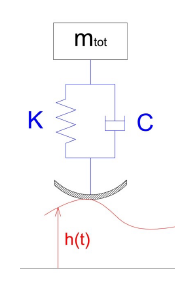

From Newton's law, it is possibile to obatin the dynamic equation of the system, set as a differential equation.

*Dynamic equation*: $\ddot  z = k/m(z-h)+c/m(\dot h-\dot z)$

The data are stored and declared in a specific matlab program:

dati = 'DatiSospensione';
open(dati)
run(dati)

warning('off','all')

Some of them are missing but they can be computed as following:

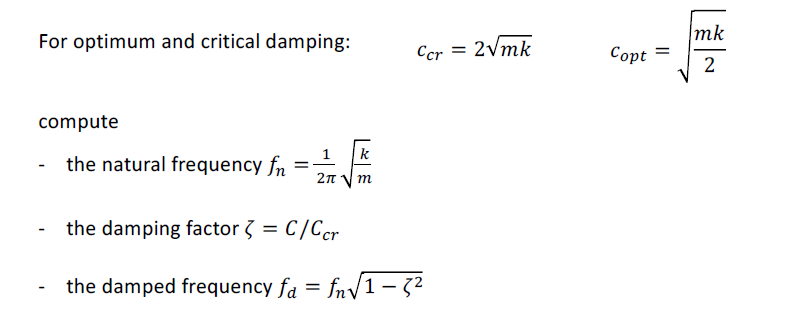

m = ms+mu;
c_cr = 2*sqrt(m*k);
c_opt = sqrt(m*k/2);

f_n = 1/2/pi*sqrt(k/m);
damping_factor = c/c_cr;
f_d = f_n*sqrt(1-damping_factor^2);

Since we are dealing with a differential equation, initial condiotions are fundamental. In this case they are both null.

z0 = 0;
zd0 = 0;

## **Analyse the vertical motion of the sprung mass **

- **Step variation of the road profile h**

Fundamental law**: **To have everything parametrised.

For this reason it is necessary to set some paramters usefull for the Simulink simulation.

h = 5/100; %5 cm = 5/100 m
t0 = 2;
slope = h/0.01; %slope for the step signal

**NOTE: **The step signal is modeled as a ramp saturated, since the derivative of a step is an impulse. Since we are dealing with a physical model, this translate into an impulsive velocity. This mathematically lead to an infinite acceleration. Here the reason why the step is modeled like that.

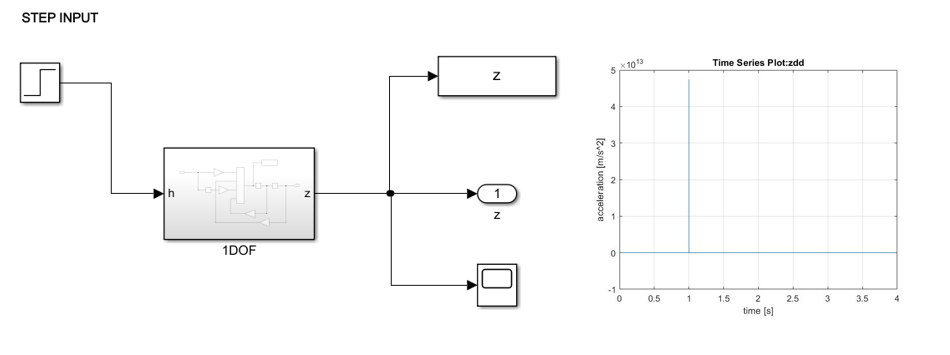

Therefore, the parameters for the ramp signal have to be defined.

h = 5/100; %5 cm = 5/100 m
t0 = 2;
slope = h/0.01; %slope for the step signal

The slope has been calcualted simly as $m=\frac{y}{x}$

Starting from the dynamic equation, the simulink model can be build.

Not only it can be found in the lecture's slides but also it deduciable within few minutes.

*Model hyperlinked**. If the fileas are still in the desktop, you can access the simulink model by double clicking the image.*

[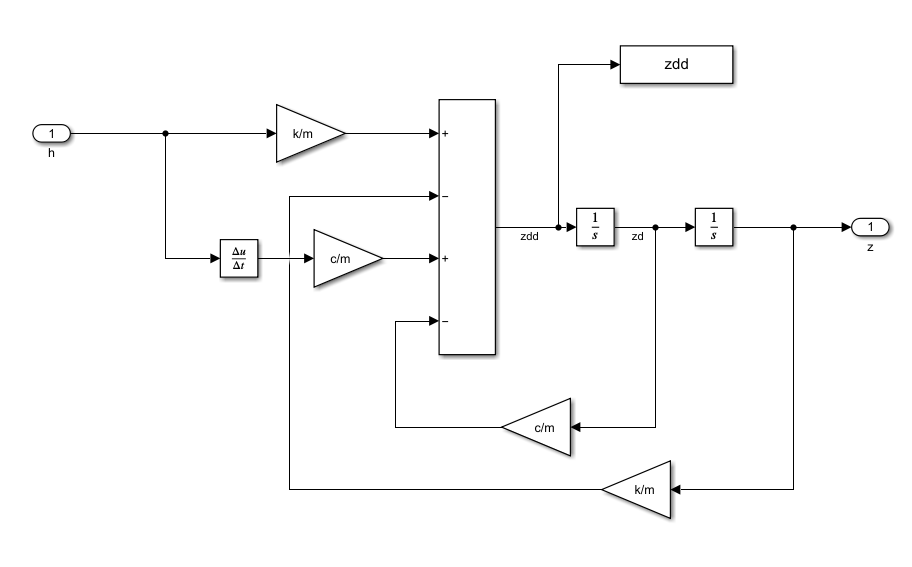](matlab:open('C:\Users\Utente\Desktop\VDS\ES01\sim_ES01_01.slx'))

Meanwhile the inputs and the outputs are the following ones:

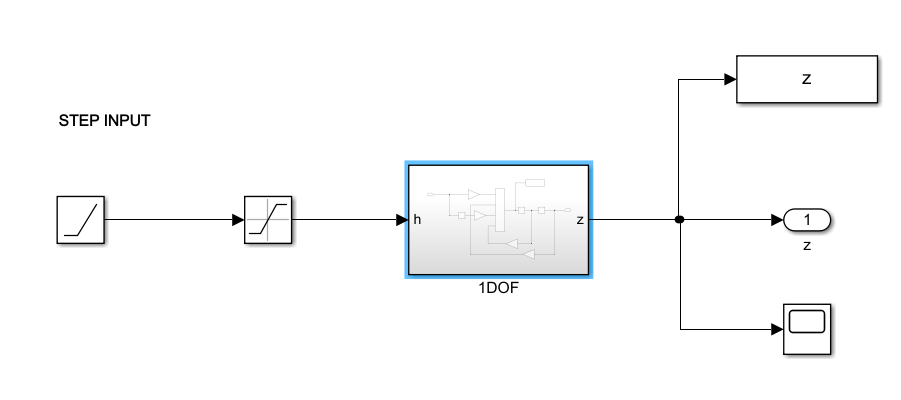

Everything is set to evaluated the vertical motion, the simulation can be started.

nfile = 'sim_ES01_01';
open(nfile)
sim(nfile)

- Acceleration results.

figure(1)
plot(zdd(:,1),'linewidth',1.5) %zdd from simulink is in m!!!
xlabel('time [s]')
ylabel('acceleration [m/s^2]')
grid on
hold on

Even if it's a *5cm* displacement, the acceleration to which the suspension is subject to is notable. In the forst case the damping is equal to the optimal one, which translates into the most efficent behaviour possible. This can be assesed by looking at the displacement.

- Displacement results.

figure(2)
plot(z(:,1)*1000,'linewidth',1.5) %results are in [m], for displacement would be recommended to use [mm]
xlabel('time [s]')
ylabel('displacement[mm]')
grid on
hold on

The displacement results are satisfactory, in fact for a *5cm* input only a peak of 7cm is obtained, and the displacement nearly immediatly converges toward an equilibrium (equal to the input vale of 5cm).

- **Critical damping value**

Now it is requested to substitue the value of *c *with the critical one.

**NOTE**: The critical damping mathematically is the value of *c* such that the corresponding dynamic equation results collapse to a repeated real root equal to $-\omega_n$ (natural frequency). The solution represent a *vibrating system*. In other words, is the value of damping for which the system is unstable. 

- For values of $c>c_{cr}$ the solution represents a nonoscillatory response. Such response is called an `overdamped system` and does not oscillate, but rather returns to its rest position exponentially

- For values of $c<c_{cr}$ the result is a sinwave, resulting in a complex conjugate pair of roots. The motion oscillates and this is called an `underdamped system`.

Hence, if the damping is less then critical, the motion vibrates, and critical damping corresponds to the smallest value of damping that results in no vibration. Critical damping can also be thought of as the  value of damping that separates nonoscillation from oscillation.

The concept of critical damping provides a useful value to discuss level of damping in a system, separating the physical phenomenon of oscillation and no oscillation.

From a ***physical point of view ***critical damping is a desirable tradeoff between having enough damping to prevent oscillation and not so much  damping that the system uses too much energy or causes too large a phase lag.

Having explained what is the critical damping, it is now possible to evaluate the system responce to it.

c = c_cr;

Nothing respect to before has changed, therefore another simulation can be launched using the same model as before.

nfile = 'sim_ES01_01';
open(nfile)
sim(nfile)

- Acceleration results.

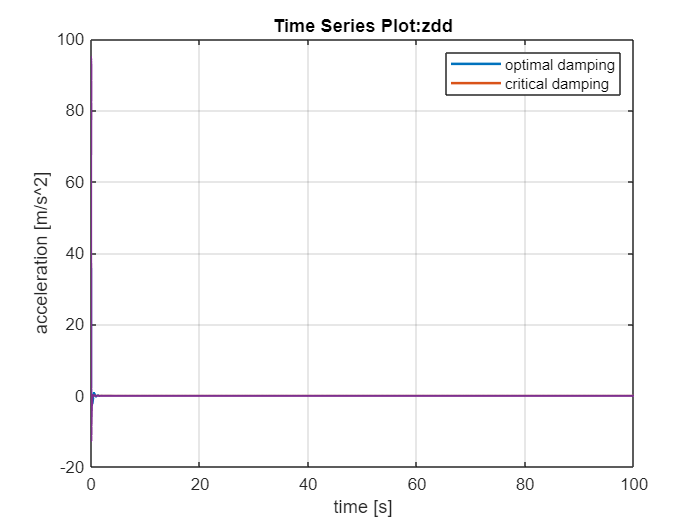

figure(1)
plot(zdd(:,1),'linewidth',1.5) %zdd from simulink is in m!!!
xlabel('time [s]')
ylabel('acceleration [m/s^2]')
legend('optimal damping','critical damping')
grid on
hold on

Here it is possible to observe the effects of the critical damping. In fact, meanwhile for *c=c_opt* the maximum acceleration registered is about *35m/s^2*, having *c=c_cr* implies a peak of *94m/s^2*. Being it the smallest amount of damping which does not imply osciallatory motion, it is resonable that it implies an higher acceleration, since the system applies less resistance than before to the motion.

This due to the fact that the critical damping is that value for which the damping capacity of the damper it at its lower limit.

- Displacement results.

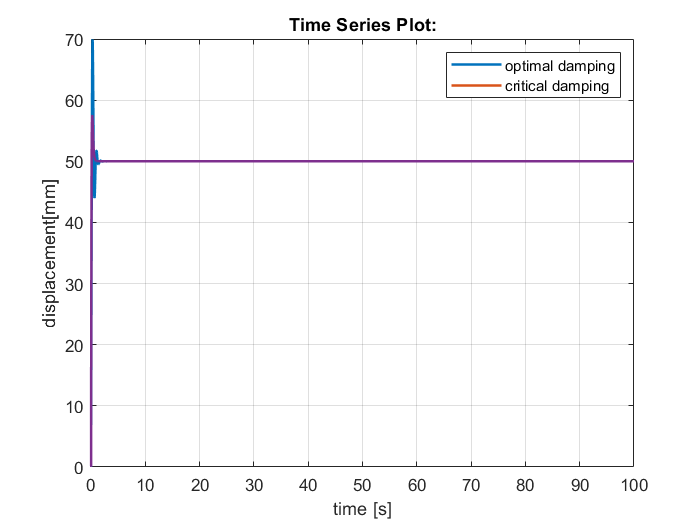

figure(2)
plot(z(:,1)*1000,'linewidth',1.5) %results are in [m], for displacement would be recommended to use [mm]
xlabel('time [s]')
ylabel('displacement[mm]')
legend('optimal damping','critical damping')
hold on
grid on

Being the optimum damping 8 times lower than the ciritical one, the system results into being underdamped. For this reason, it converges toward an equilibrium in loger time and the peaks to which it is subjected are higher. 

## **Frequency responce**

- **Sine road profile h**

New input is set, and with it new parameters.

h0 = 2/100; %h0 in cm
lambda = 2;

However, 3 different sinewaves are set as input, since three different velocities are given. Being *V* a paramter over which the road profile is based on, here it is why three different cases are needed.

#### V = 10 km/h

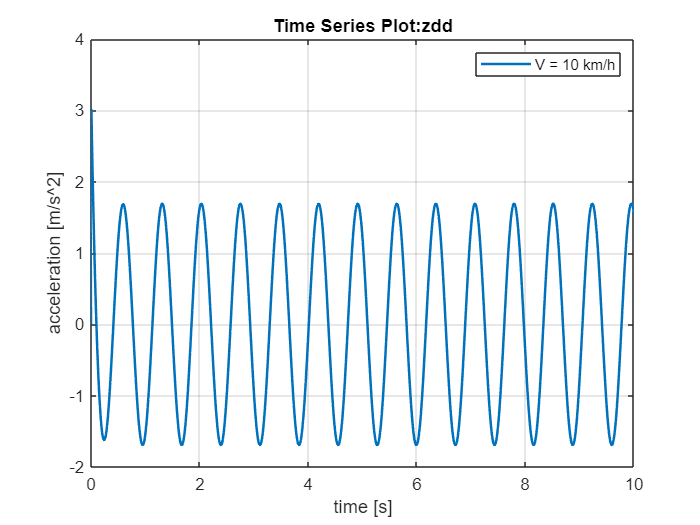

v = 10/3.6; %m/s

nfile = 'sim_ES01_02';
open(nfile)
sim(nfile)

figure(3)
plot(zdd(:,1),'linewidth',1.5) %zdd from simulink is in m!!!
xlabel('time [s]')
ylabel('acceleration [m/s^2]')
legend('V = 10 km/h')
grid on
hold on

Being the input a sinewave, the displacement and acceleration have to be harmonic as well.  Resonable values of acceleration are found. 

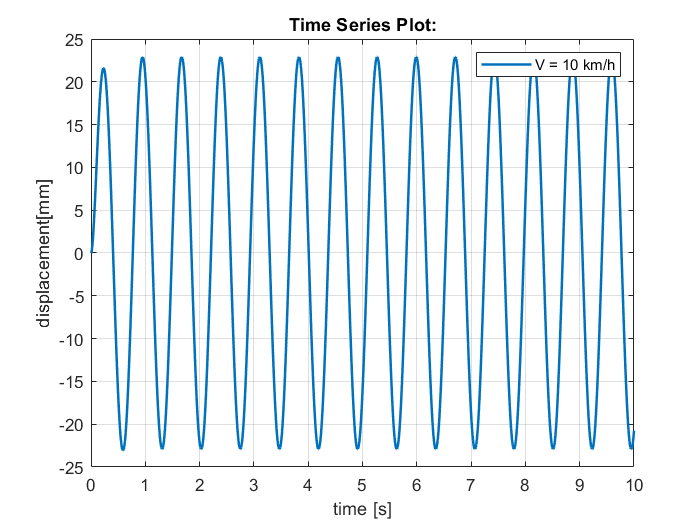

figure(4)
plot(z(:,1)*1000,'linewidth',1.5) %results are in [m], for displacement would be recommended to use [mm]
xlabel('time [s]')
ylabel('displacement[mm]')
legend('V = 10 km/h')
hold on
grid on

Note how both $z$ and $\ddot z$ are sinusoidal, since the double derivative of a* sin* is a *sin *with opposite sign.

#### V = 50 km/h

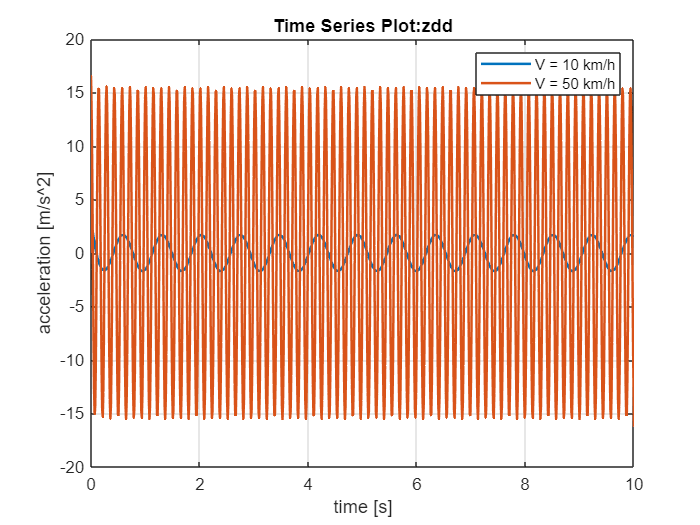

v = 50/3.6; %m/s

nfile = 'sim_ES01_02';
open(nfile)
sim(nfile)

figure(3)
plot(zdd(:,1),'linewidth',1.5) %zdd from simulink is in m!!!
xlabel('time [s]')
ylabel('acceleration [m/s^2]')
legend('V = 10 km/h','V = 50 km/h')
grid on
hold on

It is intresting how incresing the input frequency (being *V* directly connected to $\omega$) implies an accelration responce with higher amplitude and higher frequency.

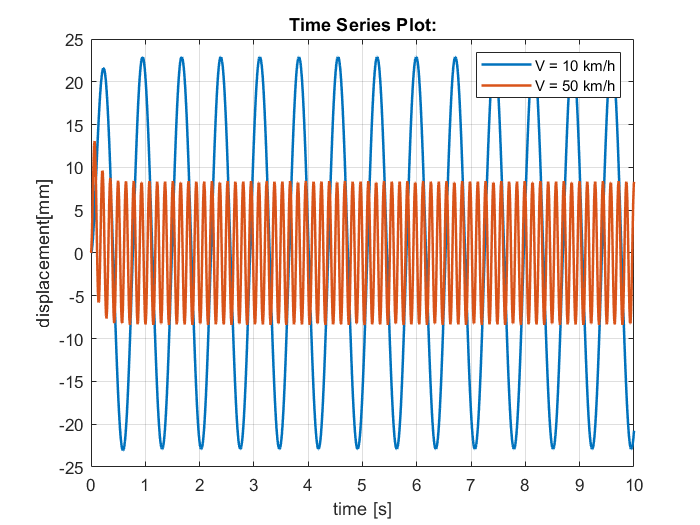

figure(4)
plot(z(:,1)*1000,'linewidth',1.5) %results are in [m], for displacement would be recommended to use [mm]
xlabel('time [s]')
ylabel('displacement[mm]')
legend('V = 10 km/h','V = 50 km/h')
hold on
grid on

Regardng the displacement instead, the frequency is even higher here, however the amplitude decreases.

#### V = 130 km/h

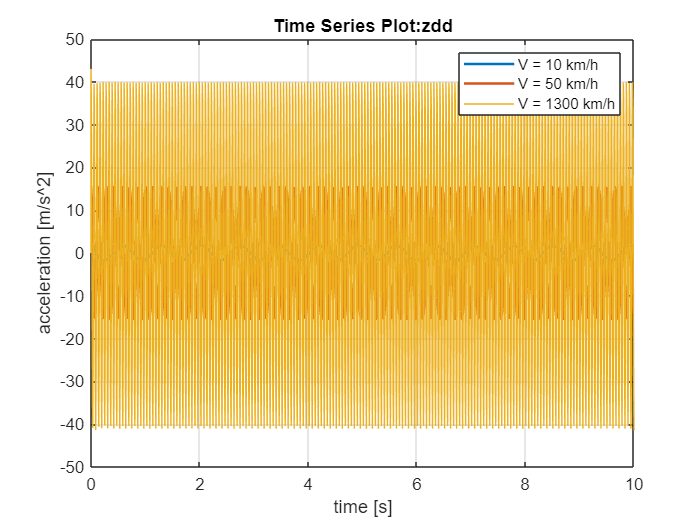

v = 130/3.6; %m/s

nfile = 'sim_ES01_02';
open(nfile)
sim(nfile)

figure(3)
plot(zdd(:,1),'linewidth',0.5) %zdd from simulink is in m!!!
xlabel('time [s]')
ylabel('acceleration [m/s^2]')
legend('V = 10 km/h','V = 50 km/h','V = 1300 km/h')
grid on
hold on

The increase of amplitude and frequency is even enhanced using a velocity of *130km/h*.

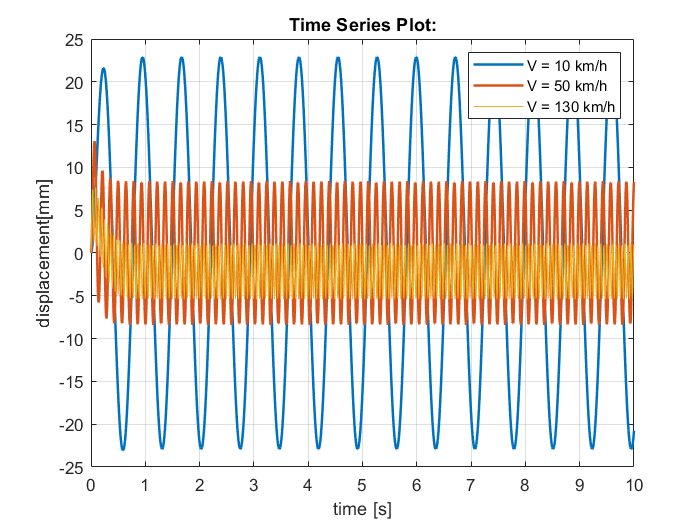

figure(4)
plot(z(:,1)*1000,'linewidth',0.5) %results are in [m], for displacement would be recommended to use [mm]
xlabel('time [s]')
ylabel('displacement[mm]')
legend('V = 10 km/h','V = 50 km/h','V = 130 km/h')
hold on
grid on

The safe effects of before are observed. For higher input frequency, the displacement amplitude reduces but its frequency increases.

#### Chirp signal

The chirp signal is a sin wave signal which keeps its amplitude constant (and euqal to 1) but increases its frequency linearly with time.

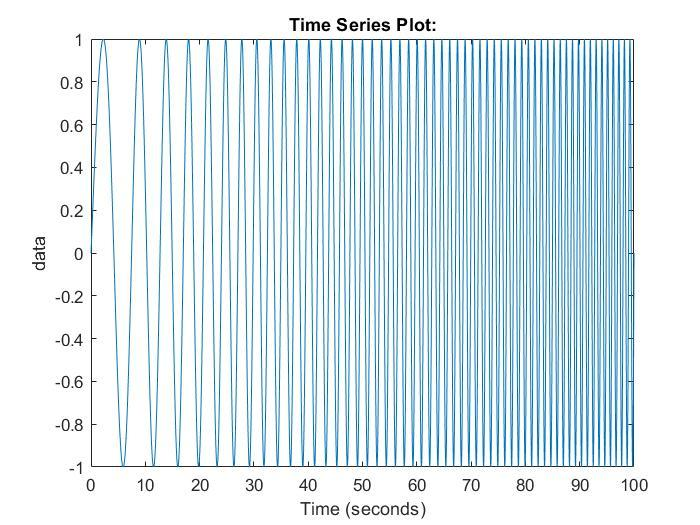

Firstly, to let the chirp to have a significative range of frequencies, the simulation time has to be increased to *100s*. Also initial and final velocities are given.

Ts = 100;
V_in = 1/3.6;
V_end = 130/3.6;

The Simulink chirp block requires the initial and final frequencies.  To compute them the same formulation used for the sinewave can be used. 


$$\omega = 2\pi \frac V\lambda$$


w_in = 2*pi*V_in/lambda;
w_end = 2*pi*V_end/lambda;

Now the result can be computed and plotted.

nfile = 'sim_ES01_03';
open(nfile)
sim(nfile)

Error due to multiple causes.

Caused by:
    Error using ES01_MATLAB_NOTES (line 123)
    Invalid setting in 'sim_ES01_03/1DOF1/To Workspace' for parameter 'Decimation'.
        Error using ES01_MATLAB_NOTES (line 123)
        Error evaluating parameter 


figure(5)
plot(zdd(:,1),'linewidth',0.5) %zdd from simulink is in m!!!
xlabel('time [s]')
ylabel('acceleration [m/s^2]')
legend('Chirp  signal')
hold on
grid on
figure(6)
plot(z(:,1)*1000,'linewidth',0.5) %results are in [m], for displacement would be recommended to use [mm]
xlabel('time [s]')
ylabel('displacement[mm]')
legend('Chirp  signal')
hold on
grid on